# Interpolación de una imagen en 2D

La **interpolación en 2D** es un proceso que permite estimar valores intermedios dentro de una imagen o superficie bidimensional a partir de un conjunto discreto de puntos conocidos. En el contexto del procesamiento de imágenes, se utiliza cuando es necesario **redimensionar**, **rotar** o **reconstruir** una imagen, manteniendo una apariencia continua y evitando bordes abruptos o pixelados.

Matemáticamente, la interpolación 2D considera la imagen como una función $f(x,y)$ definida sobre una malla de puntos. Cuando se requieren valores en posiciones no enteras, estos se calculan combinando los valores de píxeles vecinos según un método determinado, como:

- **Interpolación más cercana (nearest-neighbor):** asigna el valor del píxel más próximo.

- **Interpolación bilineal:** promedia ponderadamente los cuatro píxeles más cercanos.

- **Interpolación bicúbica:** utiliza 16 píxeles vecinos y produce resultados más suaves.

Este proceso es fundamental para la **reconstrucción de imágenes**, **registro espacial** y **transformaciones geométricas** en aplicaciones médicas, industriales y científicas.

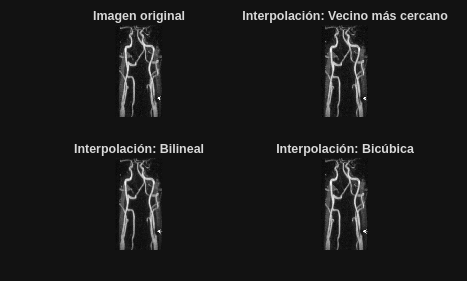

clear;
close all;

% Leer imagen base (puede ser cualquier imagen)
I = imread("/home/erit/Desktop/Imagenes/angioRM2.pgm");

% Definir factor de escala
scale = 4;

% Obtener tamaño original
[M, N] = size(I);

% Crear nueva malla de coordenadas
[x, y] = meshgrid(1:N, 1:M);
[xq, yq] = meshgrid(linspace(1, N, N*scale), linspace(1, M, M*scale));

% --- Interpolación por vecino más cercano ---
I_nearest = uint8(interp2(x, y, double(I), xq, yq, 'nearest'));

% --- Interpolación bilineal ---
I_bilinear = uint8(interp2(x, y, double(I), xq, yq, 'linear'));

% --- Interpolación bicúbica ---
I_bicubic = uint8(interp2(x, y, double(I), xq, yq, 'cubic'));

% Mostrar resultados
figure;
subplot(2,2,1);
imshow(I, []);
title('Imagen original');

subplot(2,2,2);
imshow(I_nearest, []);
title('Interpolación: Vecino más cercano');

subplot(2,2,3);
imshow(I_bilinear, []);
title('Interpolación: Bilineal');

subplot(2,2,4);
imshow(I_bicubic, []);
title('Interpolación: Bicúbica');

## Haciendo un zoom para notar las diferencias entre los métodos

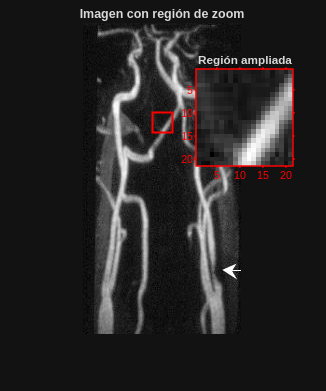

orig_window = [70 90 20 20];
scaled_window = orig_window * scale;

region = ventana_con_zoom(I,orig_window);

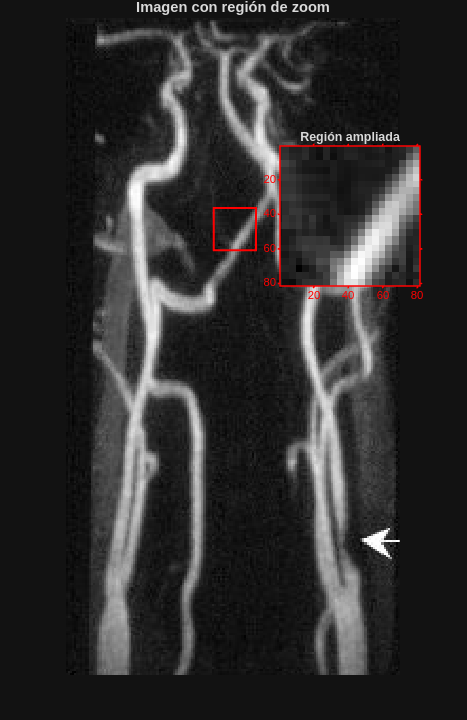

region_nearest  = ventana_con_zoom(I_nearest,scaled_window);

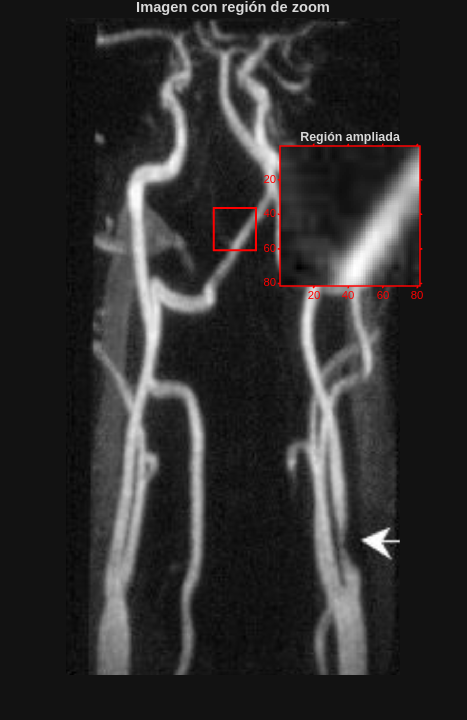

region_bilinear = ventana_con_zoom(I_bilinear,scaled_window);

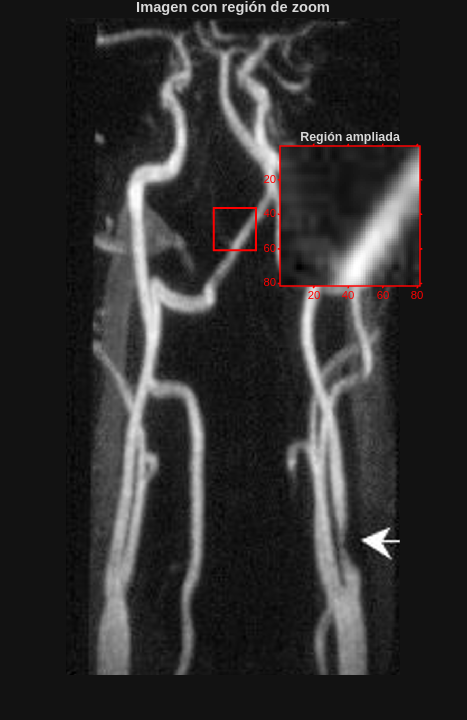

region_bicubic  = ventana_con_zoom(I_bicubic,scaled_window);

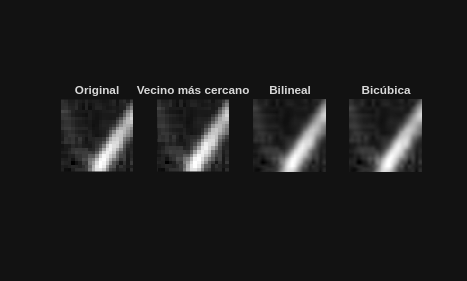

figure;

subplot(141)
imshow(region, []);
title('Original');

subplot(142)
imshow(region_nearest, []);
title('Vecino más cercano');

subplot(143)
imshow(region_bilinear, []);
title('Bilineal');


subplot(144)
imshow(region_bicubic, []);
title('Bicúbica');

# Rotación de una imagen

La **rotación de una imagen** es una transformación geométrica que consiste en girar todos los píxeles alrededor de un punto fijo, normalmente el **centro de la imagen**. Matemáticamente, cada píxel original en la posición $(x, y)$ se transforma a una nueva posición $(x', y')$ mediante una **rotación por un ángulo** $\theta$:  


$$
\[
\left[
\begin{array}{c}
x' \\[4pt]
y'
\end{array}
\right]
=
\left[
\begin{array}{cc}
\cos\theta & -\sin\theta \\[4pt]
\sin\theta & \cos\theta
\end{array}
\right]
\left[
\begin{array}{c}
x \\[4pt]
y
\end{array}
\right]
\]$$


Este modelo vectorial representa cómo cada punto del plano se desplaza según una rotación **antihoraria** alrededor del origen.  

Durante este proceso, algunos **píxeles de la imagen resultante no corresponden exactamente** a coordenadas enteras del dominio original. Para asignarles un valor de intensidad, se utilizan técnicas de **interpolación** (por ejemplo, bilineal o bicúbica), que estiman el valor de cada píxel nuevo a partir de los píxeles vecinos.  

Asimismo, pueden aparecer **zonas vacías** en la imagen rotada (partes negras o sin datos) debido a que no existen píxeles originales que se correspondan con esas posiciones. Estas áreas se pueden rellenar con un valor fijo (como 0) o recortar la imagen para mantener solo la región válida tras la rotación.

% Ángulo de rotación (en grados)
theta = 30;
theta_rad = theta * pi/ 180;

% Tamaño de la imagen
[M, N] = size(I);

% Centro de la imagen
cx = (N+1)/2;
cy = (M+1)/2;

% Matriz de rotación
R = [cos(theta_rad) -sin(theta_rad); 
     sin(theta_rad)  cos(theta_rad)];

% Crear grillas de coordenadas
[x, y] = meshgrid(1:N, 1:M);

% Convertir a coordenadas centradas en (0,0)
x_c = x - cx;
y_c = y - cy;

% Aplicar rotación: [x'; y'] = R * [x; y]
coords = [x_c(:)'; y_c(:)'];
rot_coords = R * coords;

x_rot = reshape(rot_coords(1, :) + cx, M, N);
y_rot = reshape(rot_coords(2, :) + cy, M, N);

% revisar como quedaron colocados los valores de los índices de pixeles

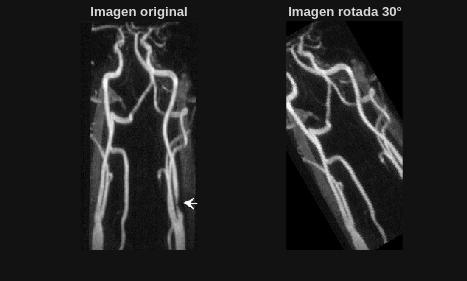


% Interpolación de los nuevos valores
% Los valores de x_rot y y_rot ya fueron reajustados para tener los nuevos
% índices y escalados
X_rot = interp2(x, y, I, x_rot, y_rot, 'nearest', 0);

% Mostrar resultados
figure;
subplot(1,2,1);
imshow(I, []);
title('Imagen original');

subplot(1,2,2);
imshow(X_rot, []);
title(['Imagen rotada ', num2str(theta), '°']);

# Proyección no ortogonal de un volumen

En imágenes médicas volumétricas, como **TAC o MRI**, muchas veces se requiere visualizar cortes o rebanadas que **no se alinean con los planos ortogonales** del volumen (axial, sagital o coronal). Este proceso se conoce como **proyección o rebanado no ortogonal**.

Matemáticamente, se define un **plano de corte arbitrario** mediante un **punto de paso** y un **vector normal**, y se construyen coordenadas sobre ese plano. Cada punto del plano se proyecta en las coordenadas del volumen 3D original, y se obtiene su valor mediante **interpolación trilineal** de los voxeles vecinos.

Este procedimiento permite:

- Explorar estructuras internas desde **ángulos no convencionales**.

- Visualizar relaciones anatómicas complejas que no se capturan en cortes ortogonales.

- Obtener imágenes diagnósticas precisas sin necesidad de reconstruir físicamente el volumen.

Aunque las imágenes resultantes no se alinean con los ejes originales, la **interpolación garantiza que cada píxel de la rebanada contenga un valor representativo del volumen**, permitiendo un análisis clínico y cuantitativo confiable.

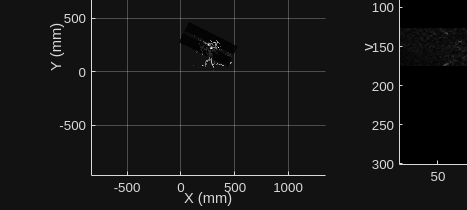

V = dicomread("/home/erit/Desktop/Imagenes/dicom_chest/E1154S7I.dcm");
V = double(squeeze(V));

% Leer el volumen DICOM
[rows, cols, num_slices] = size(V);

dx = 1; dy = 1; dz = 1;

% Crear grillas espaciales reales
[x, y, z] = meshgrid(...
    (0:cols-1)*dx, ...
    (0:rows-1)*dy, ...
    (0:num_slices-1)*dz);

%% === 2. Definir el plano de corte ===
p0 = [mean(x(:)), mean(y(:)), mean(z(:))]; % pasa por el centro del volumen
n = [1, 2, 1];  % vector normal oblicuo
n = n / norm(n);

slice_size = max([dx*cols, dy*rows]) / 2;
Ns = 300;  % resolución de la rebanada
[u, v] = meshgrid(linspace(-slice_size, slice_size, Ns));

% Ejes ortogonales al vector normal
tmp = [0 0 1];
if abs(dot(tmp, n)) > 0.9
    tmp = [0 1 0];
end

u_dir = cross(n, tmp); 
u_dir = u_dir / norm(u_dir);
v_dir = cross(n, u_dir);

% Coordenadas 3D de los puntos del plano
Xq = p0(1) + u*u_dir(1) + v*v_dir(1);
Yq = p0(2) + u*u_dir(2) + v*v_dir(2);
Zq = p0(3) + u*u_dir(3) + v*v_dir(3);

%% === 3. Interpolación del volumen ===
V_slice = interp3(x, y, z, V, Xq, Yq, Zq, 'linear', 0);

%% === 4. Visualización ===
figure('Position',[100 100 1000 450]);

subplot(1,2,1);
isosurface(x, y, z, V, max(V(:))*0.5);
axis equal; grid on; hold on;
xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('Z (mm)');
title('Volumen DICOM con plano de corte');

% Plano de corte
surf(Xq, Yq, Zq, V_slice, 'EdgeColor','none','FaceAlpha',0.8);
colormap turbo; lighting gouraud; camlight;

subplot(1,2,2);
imagesc(V_slice);
axis image; colormap gray;
title('Rebanada no ortogonal');
xlabel('u'); ylabel('v');